Matching

Ii = imread('radiografia-de-torax.jpg'); % Reemplaza 'nombre_de_tu_imagen.jpg' con el nombre y la extensión de tu imagen

% Paso 2: Convertir Ii a escala de grises
Ii_gray = rgb2gray(Ii);

% Paso 3: Calcular el histograma de Ii
Hi = imhist(Ii_gray);

% Paso 4: Calcular la PDF de Ii
total_pixeles = numel(Ii_gray); % Obtener el número total de píxeles en la imagen
Pi = Hi / total_pixeles; % Normalizar el histograma para obtener la PDF

% Paso 5: Calcular la transformación de sumas acumuladas de Ii
Ti = cumsum(Pi);

% Paso 6: Calcular la transformación de sumas acumuladas de la imagen de referencia Io
Io = ones(size(Ii)); % Crear una imagen blanca del mismo tamaño que Ii
Io_gray = rgb2gray(Io); % Convertir la imagen blanca a escala de grises
Po = ones(256, 1) / 256; % Crear una PDF uniforme para la imagen blanca
To = cumsum(Po); % Calcular la transformación de sumas acumuladas de la PDF

% Paso 7: Ajustar Io utilizando la transformación de sumas acumuladas
Io_eq = Io; % Inicializar la imagen ajustada como una copia de Io

% Obtener el tamaño de la imagen
[m, n] = size(Ii);

% Aplicar la transformación de sumas acumuladas a Io
for i = 1:m
    for j = 1:n
        % Leer el nivel de gris de pixel de Ii (ese nivel llamalo Li)
        Li = Ii(i,j) + 1;
        
        % Encontrar Ti(Li)
        Ti_Li = Ti(Li);
        
        % Busca el valor de Ti(Li) en To (dependiendo del nivel de gris To)
        To_index = min(max(round(255 * Ti_Li), 1), 256);
        
        % Asignar al pixel de Io el valor de Lo
        Lo = round(255 * To(To_index));
        Io_eq(i,j) = Lo;
    end
end

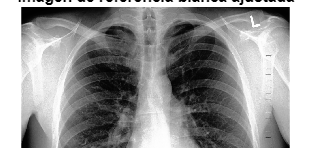

% Mostrar la imagen Io_eq
imshow(uint8(Io_eq));
title('Imagen de referencia blanca ajustada');